# Test concept: Drop tracking algorithm

**Aim: **Initial script to test concept for drop tracking. 

Code developed using model video (also used in initial development of video-processing workflow): **SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi**

**Log:**

**30-Jan; SWC.** Started code. Tested data tabulation for 1 frame.

**31-Jan; SWC.** Added code to tabulate data for all drops in all frames. 

**1-Feb; SWC. **Added comments to script. Full data table exported and labelled manually, so can use to test drop mapping algorithm before combining with ML model. data table which can be queried contains: 1) frame #, 2) drop #, 3) centroid x-coordinate, 4) drop class state.

**4-Feb; SWC. **Added code for estimating coalescence time - ideal case, with only 1 coalescence event in the video. 

**5-Feb; SWC.** test on Triton video: SO5cSt 14uL_19 uL TRITON_ 50 mM 025.avi 

Added code for estimating coalescence time - complex case (multiple coalescence event in video)

clear all 
close all 
clc 

**Background information**

So far, we have scripts to: 

- Read a video and extract individual frames; 

- Perform image processing on each extracted frame and obtain information on drops (drop area, centroid coordinates, bounding box coordinates). 

A complete script (d*ropCropMULTI.m*) has also been written such that bounding box coordinates are used to crop and save individual drop images.

**Next steps**

Following detection of drops (region of interests) in each frame, we need to assign a class label for each drop - using the machine learning classification model. 

2 ways we can approach this: 

- save each drop image in a temporary subfolder, then process all the images from all frames as ONE big batch. A table containing the entries for frame number, drop number and centroid x-coordinates would have been generated earlier during the process when cropped images were saved. Thus, output (drop class predictions) from machine learning model can directly be appended to the data table as an additional column (drop class). 

- instead of saving cropped images as new files, maybe we can pass it directly to the machine learning model as part of the for loop? Though, this means the machine learning classification step will have to be performed MULTIPLE times for a given video. There is a compromise between computing time to save images as .jpg versus running the ML model multiple times.

*(still undecided which is better, need to run some tests...)*

## 1) Load video

vid_file_name = 'SO5cSt 14uL_19 uL TRITON_ 50 mM 025.avi';
% vid_file_name = 'SO5_17umL-13Wat_umL-10kfps x4mag_sh50_C001H001S0016.avi'; %<-------- user-defined input!!
vid = VideoReader(vid_file_name); %read video 
totframes = vid.NumFrames %check total num of frames in video

totframes = 463

## 2) Background generation 

n = 200;    % number of frames to use for background generation  <-------- user-defined input!!
idx = round(linspace(1,totframes,n)); %vector of index of frame number to be extracted

frameMat = []; 

% for loop to create matrix of frames - for generating background image
for i=1:numel(idx)
    frame = read(vid,idx(i)); 
    frameMat = cat(3,frameMat,frame);
end

tic
med_pix = median(frameMat,3); %compute median of each pixel across all frames in matrix
toc

Elapsed time is 2.537951 seconds.


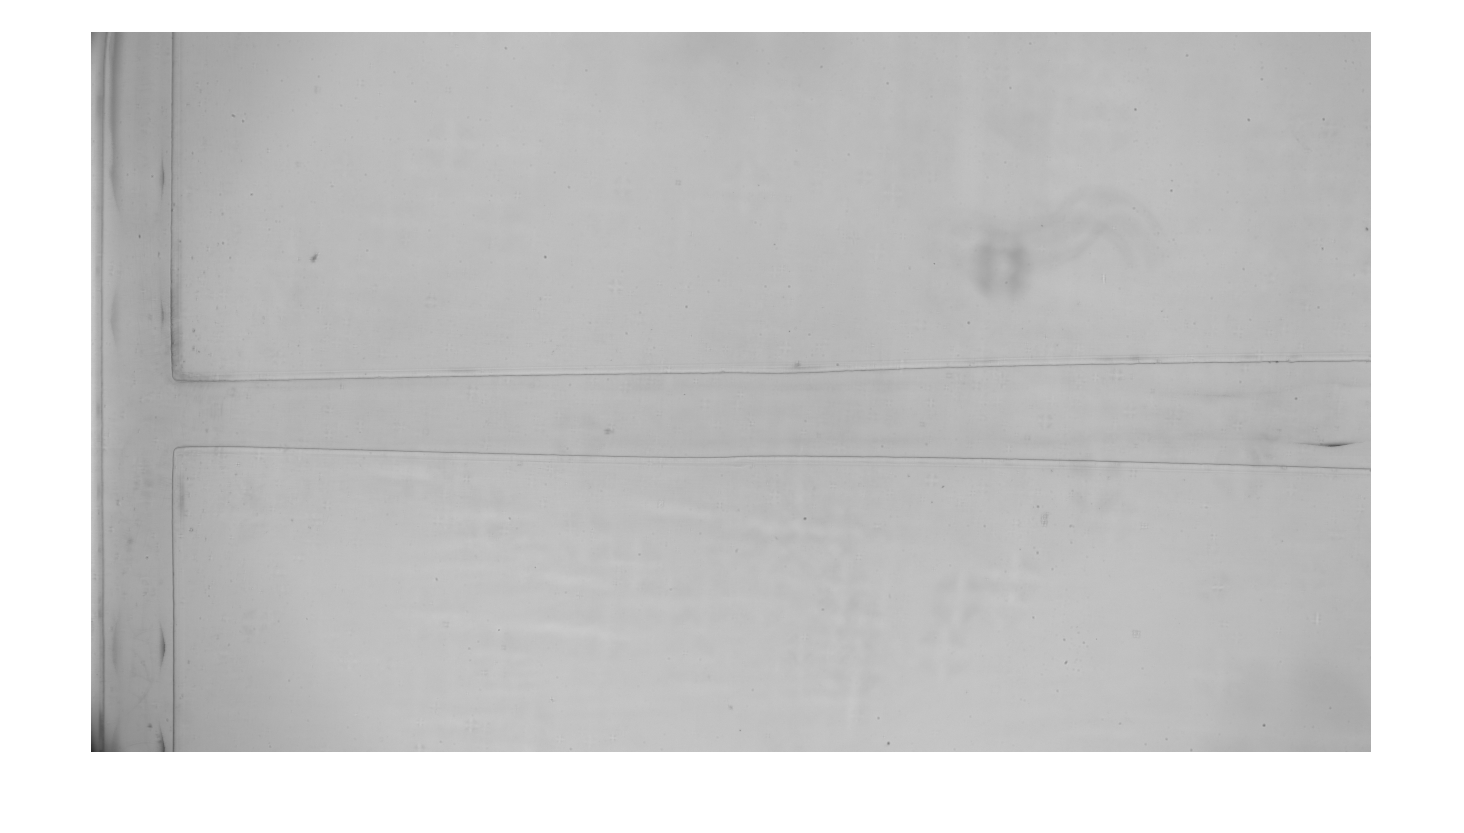


figure; imshow(med_pix);

## **3a) Generation of data table for drop tracking across frames - INITIAL TEST (ON SINGLE FRAME)**

Note: can run this if interested/ for debugging, but make sure '1.jpg' is in same folder as script.

% headers = {'Frame#' 'Drop#' 'Centroid' 'Class'};
% varTypes = {'double' 'double' 'double' 'double'};
% 
% Ttest = table('Size',[0 4],'VariableTypes',varTypes,'VariableNames',headers)
% 
% Itest = imread('1.jpg'); 
% imshow(Itest)

% % background subtraction
% subtest = med_pix - Itest; 
% % binarise image
% bintest = imbinarize(subtest, 0.2); 
% % morphological fill
% filltest = bwconvhull(bintest,'objects');
% % remove noise objects
% cfilltest = bwareaopen(filltest, 1800);
% % detect area of interest
% roitest = regionprops('table',cfilltest);
% % remove objects outside of main flow channel
% roitest(roitest.Centroid(:,1) < 140, :) = []

% frameNumtest    = 1111*ones(height(roitest),1);
% dropNumtest     =  [1:height(roitest)]';
% centroidtest = roitest.Centroid(:,1);
% classtest = [1 1 1 1 1 1 1 3]'; % random numbers just so to complete the
% table 
% 
% datatest = table(frameNumtest, dropNumtest, centroidtest, classtest, 'VariableNames', headers)
% Ttest = vertcat(Ttest,datatest)


## **3b) Generation of data table for drop tracking across frames -  PROCESS FULL VIDEO (ALL EXTRACTED VIDEO FRAMES)**

Note: In practice, should combine this with video frame extraction function (*extractVidFrames.m)* to generate a subfolder cotaining all the frames which the current script can act on. 

Here, the frames have already been extract and saved under 'extractedFrames_1' folder - make sure this is present before running the code!

% access frames
frames_folder = dir('extractedFrames_1\*.jpg'); %<--- make sure extractedFrames_1 folder is in directory!

% prepare empty table
headers = {'Frame#' 'Drop#' 'Centroid' 'Class'}; % column names: frame number, drop number, centroid x-coord, drop class state
varTypes = {'double' 'double' 'double' 'double'}; % formalities - need to tell MATLAB what the expected data class type would be. All numbers (doubles) in this case

T = table('Size',[0 4],'VariableTypes',varTypes,'VariableNames',headers)


T =

  0×4 empty table



tic
% loop through each frame in folder 
for i = 1:numel(frames_folder)
    
    % get image file name
    filename = fullfile('extractedFrames_1', sprintf('%d.jpg',i));
    % read image
    img = imread(filename);
%     figure; imshow(img)
    
    % background subtraction
    sub = med_pix - img; 
    % binarise image
    bin = imbinarize(sub, 0.2); 
    % morphological fill
    fill = bwconvhull(bin,'objects');
    % remove noise objects (anything <1800 pix^2)
    cfill = bwareaopen(fill, 1800);
    % detect area of interest
    roi = regionprops('table',cfill);
    % remove objects outside of main flow channel
    roi(roi.Centroid(:,1) < 140, :) = [];
    
    % collect data for table
    data = table(i*ones(height(roi),1),...
        [1:height(roi)]',...
        roi.Centroid(:,1),...
        randi(3, height(roi),1), ... % this data should come from ML classification prediction, but for now, just random numbers to complete table
        'VariableNames', headers);
    
    % add data to table
    T = vertcat(T,data);
    
end
toc

Elapsed time is 29.146151 seconds.



% show final data table
T

T = 4161×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

      1         1       292.72       3  
      1         2       389.74       3  
      1         3       486.85       1  
      1         4       596.44       3  
      1         5       683.88       2  
      1         6       761.43       1  
      1         7        974.7       1  
      1         8       1162.5       2  
      2         1       293.39       3  
      2         2       390.35       3  
      2         3       487.44       1  
      2         4       597.12       3  
      2         5       684.36       3  
      2         6       762.03       2  
      2         7       975.23       3  
      2         8       1162.8       1  


% save table to excel 
writetable(T, 'test001_datatable.xlsx')

The final table is what I hope would be sufficient to perform database query and compute coalescence time.

Here's the correctly labelled table:

acT = readtable('test001_datatable_labelled.xlsx',"VariableNamingRule","preserve");

## 4a) Estimate coalescence time - ideal case: only 1 coalescence event in video

- Find index of rows where class = 3

pos = find(acT.Class == 3)

pos =         8939
        8946
        8953
        8960


coal = acT(pos,:)

coal = 4×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

     1360       6       872.75       3  
     1361       6       873.22       3  
     1362       6       874.02       3  
     1363       6       874.92       3  


% % check distanced travelled per frame
% for i = 1:3 
%     dist_travelled = coal{i+1,3} - coal{i,3}
% end

- Fine first frame of coalescence

% Initiate counter
i = 1; 
% Get starting point for search
frame(i) = coal{end,1};
x(i) = coal{end,3};
drop_class(i) = coal{end,4};
% keep going back one frame until the last frame in which drops appear as
% doublet
while drop_class == 3
    frame(i+1) = frame(i) - 1; 
    drop_info = acT(acT.("Frame#") == frame(i+1), :);
    [minDist, idx] = min(abs(x(i)-drop_info{:,"Centroid"}));
    match_drop = drop_info(idx,:);
    drop_class(i+1) = match_drop.Class;
    x(i+1) = match_drop.Centroid;
    i=i+1;
end
[frame' x' drop_class']

ans = 	1.0e+03 *

    1.3630    0.8749    0.0030
    1.3620    0.8740    0.0030
    1.3610    0.8732    0.0030
    1.3600    0.8727    0.0030
    1.3590    0.8725    0.0020


coalescence_frame = frame(end) + 1

coalescence_frame = 1360

- find initial doublet formation frame

while drop_class ~= 1
    frame(i+1) = frame(i) - 1;
    drop_info = acT(acT.("Frame#") == frame(i+1), :);
    [minDist, idx] = min(abs(x(i)-drop_info{:,"Centroid"}));
    match_drop = drop_info(idx,:);
    drop_class(i+1) = match_drop.Class;
    x(i+1) = match_drop.Centroid;
    i=i+1;
end

full_search = array2table([frame' x' drop_class'],...
    'VariableNames',{'Frame#','x-coord','drop class'})

full_search = 1101×3 table
    Frame#    x-coord    drop class
    ______    _______    __________

     1363     874.92         3     
     1362     874.02         3     
     1361     873.22         3     
     1360     872.75         3     
     1359     872.48         2     
     1358     871.97         2     
     1357      871.7         2     
     1356     871.44         2     
     1355     870.91         2     
     1354     870.63         2     
     1353     870.25         2     
     1352     869.87         2     
     1351     869.59         2     
     1350     869.15         2     
     1349     868.77         2     
     1348     868.56         2     




doublet_formation_frame = frame(end) + 1 

doublet_formation_frame = 264

coalescence_time = (coalescence_frame - doublet_formation_frame)/ vid.FrameRate

coalescence_time = 36.5333

## 4b) Estimate coalescence time - complex case (multiple coalescence events in a video)

% read in table with class labels
acT = readtable('test002_Triton_datatable_labelled.xlsx',"VariableNamingRule","preserve");
% find all drops with class 3 (coalescing)
pos = find(acT.Class == 3)

pos =         3538
        3546
        3554
        3562
        3570
        3578
        3586
        3594
        3602
        3610


% create new table of 'coalescing drops'
coal = acT(pos,:)

coal = 16×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

     392        7       922.44       3  
     393        7       922.85       3  
     394        7       923.38       3  
     395        7       923.92       3  
     396        7       924.41       3  
     397        7       924.97       3  
     398        7       925.63       3  
     399        7       926.18       3  
     400        7       926.92       3  
     401        7       927.37       3  
     402        7        928.1       3  
     403        7       928.66       3  
     426        9       1172.7       3  
     427        9         1173       3  
     428        9       1173.2       3  
     429        9       1173.6       3  



% check distanced travelled per frame

% using a loop
% for i = 1:height(coal)-1 
%     dist_travelled(i) = coal{i+1,3} - coal{i,3};
% end

% using vector operation
dist_travelled = [coal.Centroid(2:end)] - [coal.Centroid(1:end-1)] 

dist_travelled =     0.4113
    0.5368
    0.5396
    0.4827
    0.5600
    0.6596
    0.5528
    0.7384
    0.4546
    0.7259


% find index to split table (separating the coalescence events)
idx = find(dist_travelled>5)

idx = 12

% additional manipulation step to facilitate for loop below 
idx = [1 idx+1]

idx =      1    13


ind_coal = cell(length(idx),1); %preallocates dimensions  
for j = 1:length(idx)
    %creates cell array that contains tables; each cell beginning with 
    %index idx(j) of table A, ending on index idx(j+1)-1
    if j ~= length(idx) %if not last pass
        ind_coal{j,:} = coal(idx(j):idx(j+1)-1,:);
    else
        ind_coal{j,:} = coal(idx(j):end,:);
    end
end

% check output 
ind_coal{1}

ans = 12×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

     392        7       922.44       3  
     393        7       922.85       3  
     394        7       923.38       3  
     395        7       923.92       3  
     396        7       924.41       3  
     397        7       924.97       3  
     398        7       925.63       3  
     399        7       926.18       3  
     400        7       926.92       3  
     401        7       927.37       3  
     402        7        928.1       3  
     403        7       928.66       3  


ind_coal{2}

ans = 4×4 table
    Frame#    Drop#    Centroid    Class
    ______    _____    ________    _____

     426        9       1172.7       3  
     427        9         1173       3  
     428        9       1173.2       3  
     429        9       1173.6       3  


% perform backtracking search for each coalescence event 

frame = cell(length(ind_coal),1); %preallocates dimensions  
x = cell(length(ind_coal),1); %preallocates dimensions  
drop_class = cell(length(ind_coal),1); %preallocates dimensions  


for k = 1:length(ind_coal)
    
    %Initiate counter
    z = 1; 
    % Get starting point for search
    frame{k}(z) = ind_coal{k}{end,1};
    x{k}(z) = ind_coal{k}{end,3};
    drop_class{k}(z) = ind_coal{k}{end,4};
   
    % keep going back one frame until the last frame in which drops appear as
    % doublet
    while drop_class{k} == 3
    frame{k}(z+1) = frame{k}(z) - 1; 
    drop_info = acT(acT.("Frame#") == frame{k}(z+1), :);
    [minDist, idxx] = min(abs(x{k}(z)-drop_info{:,"Centroid"}));
    match_drop = drop_info(idxx,:);
    drop_class{k}(z+1) = match_drop.Class;
    x{k}(z+1) = match_drop.Centroid;
    z=z+1;
    end
   
%     [frame' x' drop_class']
    coalescence_frame = frame{k}(end) + 1
   
    while drop_class{k} ~= 1
    frame{k}(z+1) = frame{k}(z) - 1;
        if frame{k}(z+1) == 0
            disp('doublet already formed at start of video, cannot identify doublet formation frame')
            break
            
        else 
            drop_info = acT(acT.("Frame#") == frame{k}(z+1), :);
            [minDist, idxx] = min(abs(x{k}(z)-drop_info{:,"Centroid"}));
            match_drop = drop_info(idxx,:);
            drop_class{k}(z+1) = match_drop.Class;
            x{k}(z+1) = match_drop.Centroid;
            z=z+1;
                    
        end
    end
    
    
    if frame{k}(end) >= 1
        doublet_formation_frame = frame{k}(end) + 1 
        coalescence_time = (coalescence_frame - doublet_formation_frame)/ vid.FrameRate
        full_search = array2table([frame{k}' x{k}' drop_class{k}'],...
            'VariableNames',{'Frame#','x-coord','drop class'})
    end       
    
    
end

coalescence_frame = 392

doublet_formation_frame = 353

coalescence_time = 7.8000

full_search = 52×3 table
    Frame#    x-coord    drop class
    ______    _______    __________

     403      928.66         3     
     402       928.1         3     
     401      927.37         3     
     400      926.92         3     
     399      926.18         3     
     398      925.63         3     
     397      924.97         3     
     396      924.41         3     
     395      923.92         3     
     394      923.38         3     
     393      922.85         3     
     392      922.44         3     
     391      921.91         2     
     390      921.44         2     
     389      921.02         2     
     388      920.48         2     


coalescence_frame = 426

doublet already formed at start of video, cannot identify doublet formation frame
